# Comparative analysis

The four models side by side, the equivalences that connect them, and the two data-driven comparisons the project set out to make.

% Bootstrap: walk up from this file until setup_paths.m is found, then put
% the library on the path. This works whether you are running the .m source
% or the generated .mlx, from any folder.
projectDir = fileparts(mfilename('fullpath'));
while ~isfile(fullfile(projectDir, 'setup_paths.m')) && ...
        ~strcmp(projectDir, fileparts(projectDir))
    projectDir = fileparts(projectDir);
end
addpath(projectDir);
setup_paths;

NDS opinion-dynamics library added to the path.
Project root: /Users/llp/Desktop/NDS_Project


## The 2x2 table

The VERTICAL axis is time discretisation and only removes the periodicity obstruction. The HORIZONTAL axis is anchoring: the governing M-matrix goes from singular to nonsingular, marginal stability becomes exponential, and the limit operator goes from rank one to full rank.

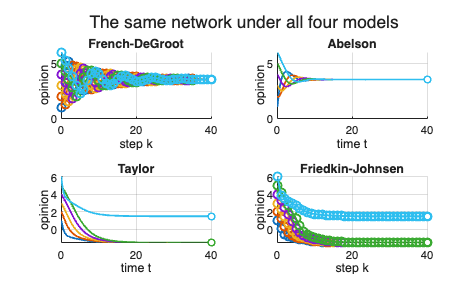

net = make_ring(6, 'SelfWeight', 0.25);
x0 = (1:6).';
u  = [-3; 0; 0; 0; 0; 3];
gamma  = [1.5; 0; 0; 0; 0; 1.5];
lambda = 1 ./ (1 + gamma);       % the matched susceptibility, see below

results = { ...
    sim_degroot(net, x0, 40),                                        'French-DeGroot'; ...
    sim_abelson(net, x0, linspace(0, 40, 300)),                      'Abelson'; ...
    sim_taylor(net, gamma, u, x0, linspace(0, 40, 300)),             'Taylor'; ...
    sim_friedkin_johnsen(net, lambda, u, x0, 40),                    'Friedkin-Johnsen'};

figure;
tl = tiledlayout(2, 2);
for k = 1:4
    plot_opinions(results{k, 1}, 'Axes', nexttile(tl), ...
        'Title', results{k, 2}, 'Legend', false);
end
title(tl, 'The same network under all four models');

## Which limit operator has which rank

fprintf('\n%-18s %-12s %s\n', 'model', 'spread', 'limit');


model              spread       limit


for k = 1:4
    r = results{k, 1};
    if all(isfinite(r.xinf))
        fprintf('%-18s %-12.4f %s\n', results{k, 2}, ...
            max(r.xinf) - min(r.xinf), mat2str(round(r.xinf.', 3)));
    else
        fprintf('%-18s %-12s %s\n', results{k, 2}, 'n/a', 'does not converge');
    end
end

French-DeGroot     0.0000       [3.5 3.5 3.5 3.5 3.5 3.5]
Abelson            0.0000       [3.5 3.5 3.5 3.5 3.5 3.5]
Taylor             3.0000       [-1.5 -1.5 -1.5 -1.5 -1.5 1.5]
Friedkin-Johnsen   3.0000       [-1.5 -1.5 -1.5 -1.5 -1.5 1.5]


## Equivalences verified numerically

These are the numerical demonstrations of the theoretical connections, and they double as the cross-model regression tests in tests/test_crossmodel.m.

fprintf('\n--- equivalences ---\n');


--- equivalences ---



% 1. Lambda = I reduces FJ to French-DeGroot.
a = sim_friedkin_johnsen(net, ones(6,1), 99*ones(6,1), x0, 30);
b = sim_degroot(net, x0, 30);
fprintf('FJ(Lambda = I) vs DeGroot           : %.2e\n', max(abs(a.X(:) - b.X(:))));

FJ(Lambda = I) vs DeGroot           : 0.00e+00



% 2. FJ equals DeGroot on the augmented graph with virtual stubborn agents.
Waug = [lambda .* net.W, diag(1 - lambda); zeros(6), eye(6)];
c = sim_degroot(Waug, [x0; u], 40, 'Predict', false);
d = sim_friedkin_johnsen(net, lambda, u, x0, 40);
fprintf('FJ vs augmented DeGroot             : %.2e\n', max(abs(c.X(1:6,:) - d.X), [], 'all'));

FJ vs augmented DeGroot             : 4.44e-16



% 3. Sampling the Abelson flow gives a DeGroot model (Lemma 17).
tau = 0.4;
e = sim_degroot(expm(-net.L * tau), x0, 30, 'Predict', false);
f = sim_abelson(net, x0, tau * (0:30));
fprintf('sampled Abelson vs DeGroot          : %.2e\n', max(abs(e.X(:) - f.X(:))));

sampled Abelson vs DeGroot          : 0.00e+00



% 4. Taylor and FJ agree when lambda_i = 1/(1 + gamma_i), for row-stochastic A.
xT = predict_limit_taylor(net.W, gamma, u, x0);
xF = predict_limit_fj(net.W, lambda, u, x0);
fprintf('Taylor vs FJ on matched parameters  : %.2e\n', max(abs(xT - xF)));

Taylor vs FJ on matched parameters  : 4.44e-16


## Cleavage: two mechanisms that look alike

Weak coupling and stubbornness both produce a visually similar split, but one is a TRANSIENT PLATEAU and the other a genuine EQUILIBRIUM. On the log axis the difference is unmistakable: the plateau eventually falls away, the equilibrium does not.

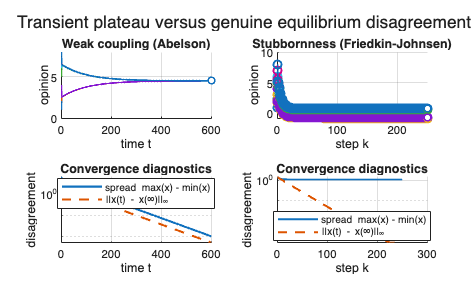

comm = make_two_communities(4, 0.02);
n = comm.n;
weak   = sim_abelson(comm, (1:n).', linspace(0, 600, 800));

strong = make_two_communities(4, 0.5);
uSplit = [-ones(4,1); ones(4,1)];
stub   = sim_friedkin_johnsen(strong, 0.85 * ones(n,1), uSplit, (1:n).', 250);

figure;
tl2 = tiledlayout(2, 2);
plot_opinions(weak,   'Axes', nexttile(tl2), 'Legend', false, 'Title', 'Weak coupling (Abelson)');
plot_opinions(stub,   'Axes', nexttile(tl2), 'Legend', false, 'Title', 'Stubbornness (Friedkin-Johnsen)');
plot_convergence(weak, 'Axes', nexttile(tl2));
plot_convergence(stub, 'Axes', nexttile(tl2));
title(tl2, 'Transient plateau versus genuine equilibrium disagreement');


fprintf('\nweak coupling  : spread falls to %.2e (transient)\n', ...
    max(weak.X(:,end)) - min(weak.X(:,end)));


weak coupling  : spread falls to 1.04e-02 (transient)


fprintf('stubbornness   : spread settles at %.4f (permanent)\n', ...
    max(stub.xinf) - min(stub.xinf));

stubbornness   : spread settles at 1.5077 (permanent)


## Three notions of importance on real data

French-DeGroot social power against the structural centralities and the brokerage measure published by Sims & Gilles (2014) for this exact matrix.

kr = load_krackhardt();
bench = krackhardt_benchmarks();
pk = social_power(kr);

comparison = table(bench.manager, pk, bench.betweenness, bench.bonacich, ...
    bench.middleman, 'VariableNames', ...
    {'manager', 'socialPower', 'betweenness', 'bonacich', 'middlemanPower'});
disp(sortrows(comparison, 'socialPower', 'descend'));

    manager    socialPower    betweenness    bonacich    middlemanPower
    _______    ___________    ___________    ________    ______________

      21          0.20114        0.176        1.348          0.147     
       7            0.143        0.048        0.776              0     
       2          0.13219        0.011        0.306              0     
      18          0.10566        0.231        1.745              0     
      14         0.071532        0.002        0.625              0     
      11         0.053174        0.004        0.344              0     
       4         0.051621        0.071        1.001           0.09     
      12         0.050614            0        0.172              0     
       1         0.047655        0.035        0.068              0     
      20         0.040663        0.02

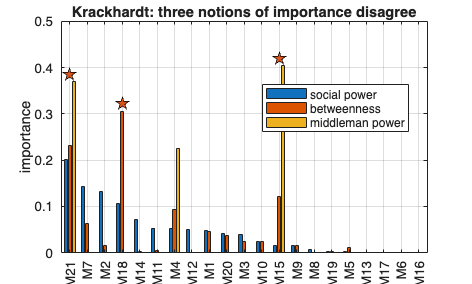


figure;
plot_influence_bars([pk, bench.betweenness, bench.middleman], ...
    'Labels', kr.labels, 'Normalize', true, 'Sort', 'descend', ...
    'SeriesNames', {'social power', 'betweenness', 'middleman power'}, ...
    'Highlight', [15 18 21], ...
    'Title', 'Krackhardt: three notions of importance disagree');

## What the comparison shows

[~, topPower]  = max(pk);
[~, topBetween]= max(bench.betweenness);
[~, topBroker] = max(bench.middleman);
rankOf = @(v, i) find(sort(v, 'descend') == v(i), 1);

fprintf('\ntop by social power    : manager %d\n', topPower);


top by social power    : manager 21


fprintf('top by betweenness     : manager %d (social power rank %d)\n', ...
    topBetween, rankOf(pk, topBetween));

top by betweenness     : manager 18 (social power rank 4)


fprintf('top by brokerage       : manager %d (social power rank %d)\n', ...
    topBroker, rankOf(pk, topBroker));

top by brokerage       : manager 15 (social power rank 13)


fprintf('\ncorr(power, betweenness) = %+.3f\n', pearson_correlation(pk, bench.betweenness));


corr(power, betweenness) = +0.608


fprintf('corr(power, brokerage)   = %+.3f\n', pearson_correlation(pk, bench.middleman));

corr(power, brokerage)   = +0.324


fprintf('corr(power, bonacich)    = %+.3f\n', pearson_correlation(pk, bench.bonacich));

corr(power, bonacich)    = +0.042



% Manager 15 is the strongest broker in the organisation yet is nearly
% powerless over opinions: brokerage controls what passes BETWEEN others,
% social power measures being LISTENED TO. Manager 18 dominates the classical
% centralities and is not a broker at all. Only manager 21 is strong on both.